clear

%%%%%%%%%%%% Constants %%%%%%%%%%%%%%%%%%%%%

% Environment
g = 9.81

g = 9.8100

r_E = 6378137 % Earth radius

r_E = 6378137

P_0 = 101325 % Base pressure Pa

P_0 = 101325

L_b = 0.0098 % Temp change K/m

L_b = 0.0098

T_b = 293.15 % Base temp K

T_b = 293.1500

Baro_exp = (-g*0.02897)/(8.3145*L_b)

Baro_exp = -3.4878


h_0 = 0 % Launch pad height

h_0 = 0


% Rocket parameters
A_rocket = pi*0.15^2

A_rocket = 0.0707

S_e = pi*0.02^2

S_e = 0.0013

I_s = 250 % Specific impulse

I_s = 250

T_max = 1000

T_max = 1000

T_min = 500

T_min = 500

Ang_max = deg2rad(10) % Max thrust vector angle

Ang_max = 0.1745

Vec_max = T_max*sin(Ang_max) % Max thrust vector force

Vec_max = 173.6482

Tilt_max = deg2rad(20) % Max safe rocket tilt

Tilt_max = 0.3491

v_land = -1 % landing speed

v_land = -1


t_P2 = 1 % Primary thruster 2% settling time

t_P2 = 1

sigma = 4/t_P2

sigma = 4

t_P = 1/sigma % Primary thruster time constant

t_P = 0.2500

t_S = 0.1 % Secondary thruster time constant

t_S = 0.1000

t_V = 0.1 % Vectoring actuation time constant

t_V = 0.1000


r_S = 0.15 % Moment arm to secondary thrusters

r_S = 0.1500

T_max_s = 1

T_max_s = 1


ang_safe = deg2rad(20)

ang_safe = 0.3491


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%% Initial conditions %%%%%%%%%%%%
Upsilon = 0;
E = 0;
N = 0;

U = 0;
V = 0;
W = 0;

P = 0;
Q = 0;
R = 0;

Phi = deg2rad(0);
Theta = deg2rad(0);
Psi = deg2rad(0);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

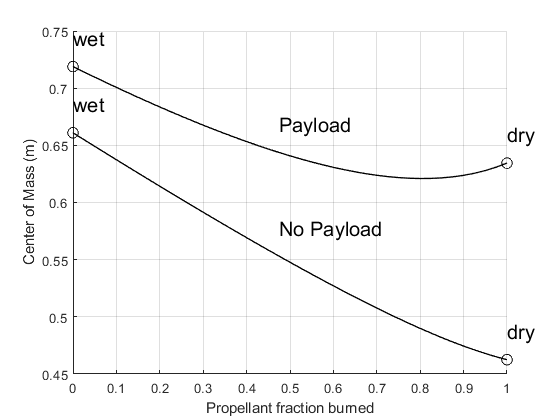

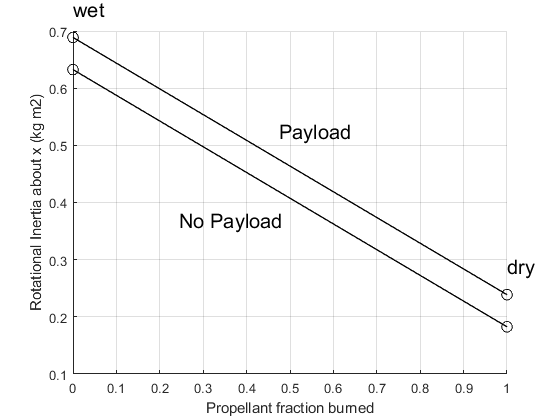

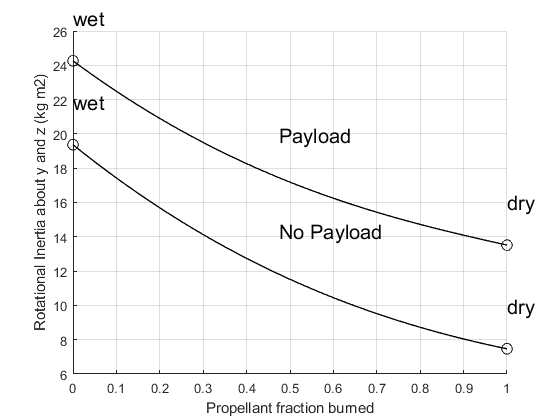

% Rocket paramaters
parameter_vary

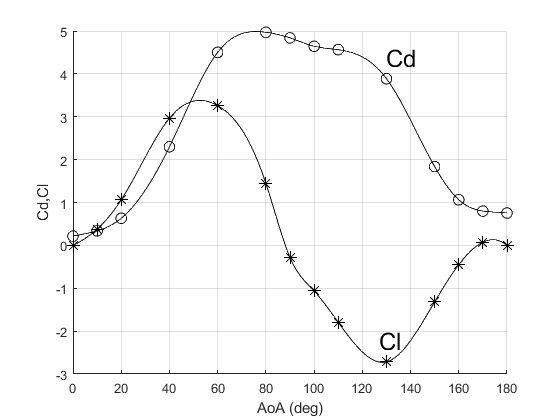

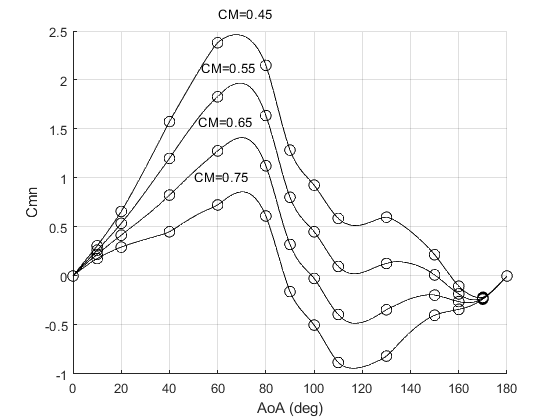

Ct_rot = -1.1887

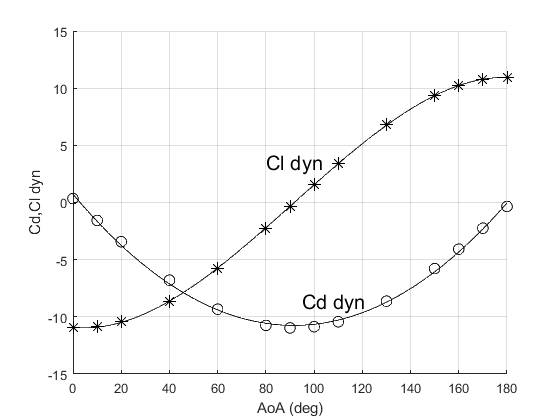

drag_wave_lookup2 = 0.7148

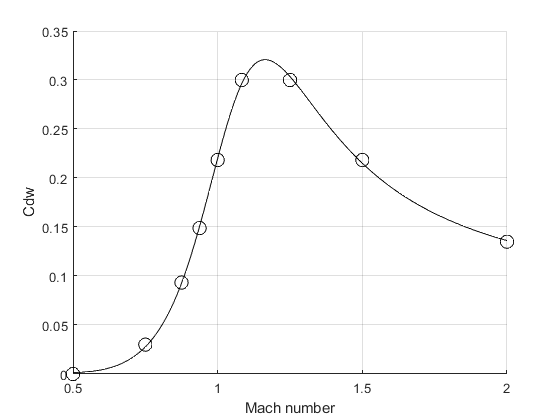

coeff_calc

wn = 5.6577

C_roll =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 11.8, Ki = 7.49, Ts = 0.02
 
Sample time: 0.02 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 2.7590
           PhaseMargin: 60.0000


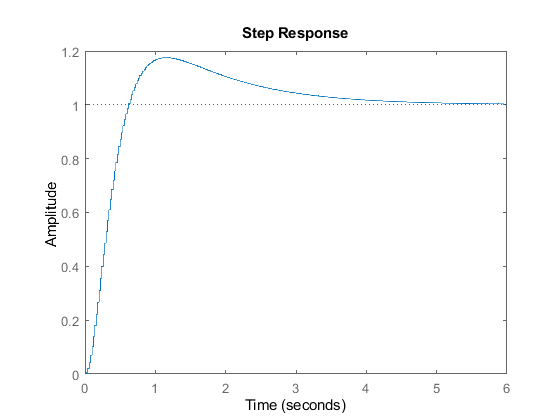

% Controllers
roll_control

Mp = 0.1000

zeta = 0.5912

p_s_want =   -2.1282 + 2.9036i
  -2.1282 - 2.9036i


p_z_want =    0.9785 + 0.0284i
   0.9785 - 0.0284i


Ki = 21.7910

Kp = 130.7460

C_climb =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 131, Ki = 21.8, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PI controller in parallel form.



zeta = 1

p_s_want =     -2
    -2


p_z_want =     0.9802
    0.9802


Kp = 0.8000

Ki = 0

C_alt =
 
  Kp = 0.8
 
P-only controller.



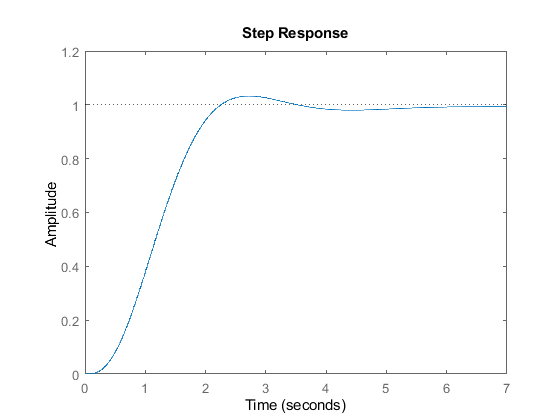

heave_control

C_rate =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 77.7, Ki = 51.6, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 2.9486
           PhaseMargin: 60.0000


C_vel =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 66.4, Ki = 1.16, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1
           PhaseMargin: 52.7928


C_pos =
 
  Kp = 0.475
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.5043
           PhaseMargin: 59.9993


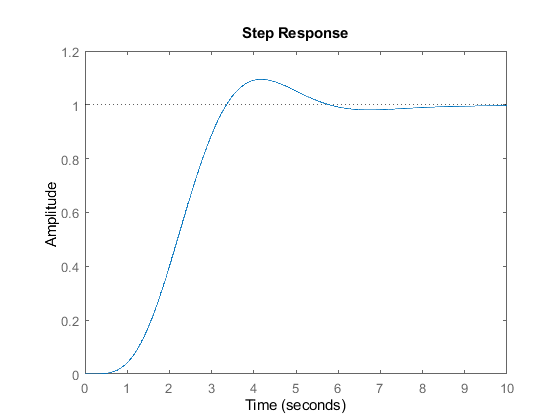

horizontal_control

Alt_sequence = [100, 100, 0];

Pos_sequence = [0, 10, 0;
                0, 10, 0];

% Alt_sequence = [500, 0];
% 
% Pos_sequence = [0, 0;
%                 0, 0];